**Writing Plotting Functions**

Like analysis functions, plotting functions in the SchwartzLab DataJoint implementation are designed to work on the Epoch, Dataset, Cell, or Multi-cell level. Instead of taking the Epoch/Dataset/Cell itself as an input, the plotting function takes a precomputed result as its input. Your plotting function can have as many axes as you want, so you can do multiple window plots. Unfortunately, the 'subplot' command is not supported inside AppDesigner windows without some extra tricks:[https://www.mathworks.com/help/matlab/creating_guis/graphics-support-in-app-designer.html](https://www.mathworks.com/help/matlab/creating_guis/graphics-support-in-app-designer.html)

So instead, I wrote some code that will just split up the display area in DataExplorer into multiple regions  if your function uses multiple axes.

Inputs and output

Here is the header line of an example plotting function

It has 3 inputs and 1 output. This is the form that all plotter functions must take. Here is an explanation of the inputs.

If your function will plot into 2 different axes, just add another one in the header line like this:

And so on... Use as many axes as you like.

The output, *tableData,* is optional. It is a struct containing any numbers associated with this plot that you would like to see displayed in a table in DataExplorer. For example, the *plotSMS* function puts the peak ON and OFF spotSize (the one with the largest response) and the suppression index for ON and OFF in *tableData* so thos numbers can be viewed along with the graph. Here is the complete code for *plotSMS.*

Notice that the normal functions that you use for plotting, like *errorbar, xlabel, ylabel, hold* can all be called with the axis as their first argument. 

Here is another example where the *entry* argument is used in a query in the plotting function to grab some external data - in this case, the SpikeTrain.

If you ever want to call your plottinng function from outside DataExplorer, just pass it a new axis using the *gca* function like this:

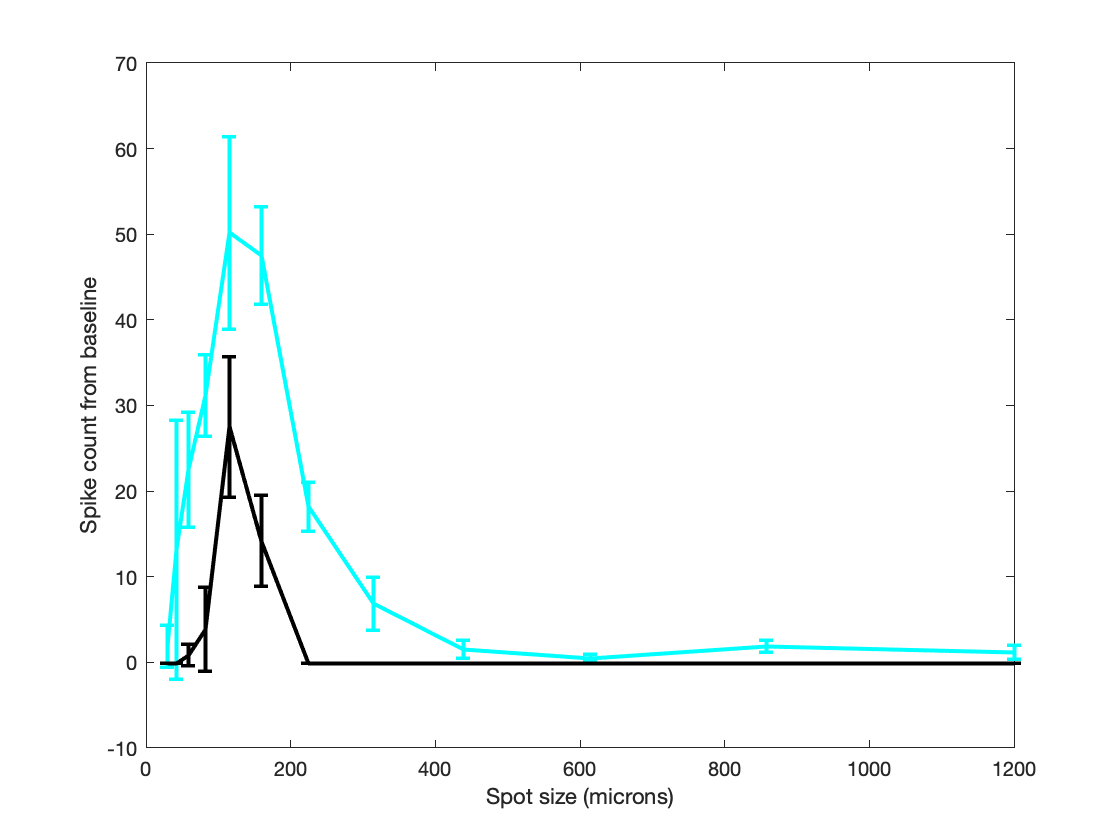

dataset = sl.Dataset & 'dataset_name="SpotsMultiSize"' & 'cell_id="051320Ac1"';
dataset_result = sl_greg.DatasetResult & dataset;
R = dataset_result.fetch1('result');
tableData = plotSMS(R,[],gca);